## **Изучение спектра звезд**

close all
clear variables

Импортируем данные из csv-файлов

spectra = importdata("spectra.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
starNames = importdata("star_names.csv");

Определим константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

Определим диапазон длин волн


nObs = size(spectra, 1)

nObs = 357

nStars = size(spectra, 2)

nStars = 7

lambda_end = lambdaStart + (nObs - 1)*lambdaDelta

lambda_end = 679.8600

lambda = (lambdaStart:lambdaDelta:lambda_end)';

Получаем индексы и минимальные интенсивности всех звезд

[stars_Ha, idx] = min(spectra)

stars_Ha = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980    0.0221


idx =    188   187   188   189   189   191   185



lambda_stars_Ha = 1:7;
for i = 1: 1: 7
    lambda_stars_Ha(i) = lambda(idx(i));
end
lambda_stars_Ha

lambda_stars_Ha =   656.2000  656.0600  656.2000  656.3400  656.3400  656.6200  655.7800



z = 1:7;
for i = 1: 1: 7
    z(i) = (lambda_stars_Ha(i) / lambdaPr) - 1;
end
z

z = 	1.0e+-3 *

   -0.1219   -0.3352   -0.1219    0.0914    0.0914    0.5181   -0.7619



speed = 1:7;
for i = 1: 1: 7
   speed(i) = z(i) * speedOfLight;
end
speed = speed'

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029



movaway = [starNames(4), starNames(5), starNames(6)]'

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


Построим график

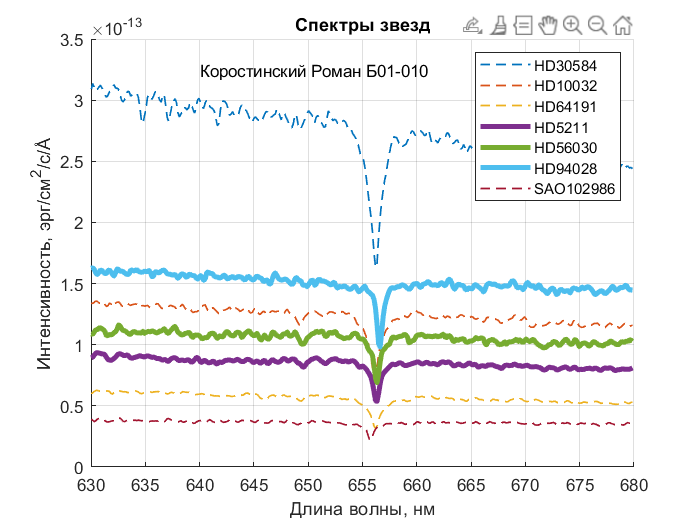

fg1 = figure;
hold on
for i = 1: 1: 7
    if speed(i) < 0
        plot(lambda, spectra(:,i), "--", "LineWidth", 1)
    else
        plot(lambda, spectra(:,i), "-", "LineWidth", 3)
    end
end
legend(starNames)
set(fg1, 'visible', 'on')
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title('Спектры звезд')
text(640, 3.25 * 10^(-13), 'Коростинский Роман Б01-010')
grid on
hold off

Сохраним график

saveas(fg1, 'spectra.png');